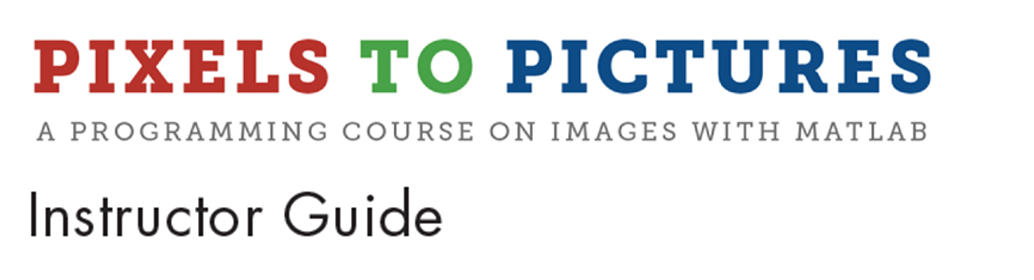

# Module 13: Applying Masks to Faces in Images

**Prerequisite Domain Knowledge:** Importing images, resizing/rotating images

**Expected Completion Time: **60 minutes

## Applying Masks to Faces in Images - Physical Activity 

*Expected Duration: 15 minutes*

### Learning Objectives

- Overlay masks on faces in printed out pictures

### Materials

- Printed out copies of several pictures from the **Image Library** folder

-     babies.jpg, cat4.jpg, curls.jpg, happy.jpg, cat5.jpg, dog1.jpg, etc.

- Color copies of Handout "Masks"

- Pairs of scissors

- Tape

### **Steps**

 
web('worksheets_and_handouts/Masks.pdf', '-browser');

Ask the students to pick the following materials for this activity:

- One print out of the Mask pictures

- One or two copies of the pictures with human or animal faces in them

- A pair of scissors

- Tape

Tell the students that they need to cut out the masks they like from the Masks Handout and place it over the human or animal faces as they see fit. Encourage them to experiment with different masks on different faces and even put more than one mask on a face (e.g. a hat and sunglasses)

Give the students some time to do this. Once completed, ask:

- *To apply a mask on a face picture what were the things they needed? *

-     The students should say they needed a face picture to put the mask on, and mask pictures to apply. Discount the scissors and tape.

- *Was it all they needed? *

-     Students may not have realized it, since their brain is doing it subconsciously, but they also needed to identify the location where they would place the mask. In other words, they are automatically locating the position of the face in the image to place the mask correctly. 

- *Was there anything they wish they could have done? *

-     Some of the faces in the pictures may be too big or too small for the masks. It might have been good if they had the ability to resize either the mask or the face image to fit perfectly.

Ask the students to keep these points in mind for the next activity where we will be applying masks to faces in MATLAB.

Encourage the students to walk around and look at what mask combinations the other students have applied to their face pictures.

## Applying Masks to Faces in Images - MATLAB

*Expected Duration: 45 minutes*

### Learning Objectives

- Overlay masks on faces in images

- Understand and develop algorithms

### Materials

- MATLAB®

### **Steps**

- Tell the students that we will now be applying masks on faces in MATLAB. 

- Before we do that, let’s take a look at all the masks that are available for the students to use. 

In the **Command Window**, type in

This should open up the following figure. Maximize the figure so that all the masks are easily visible. It is the same set of masks they just had a printout of:

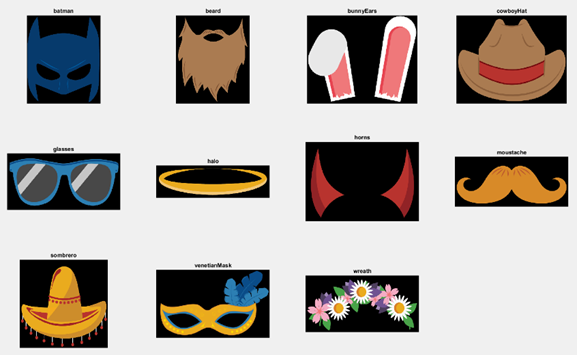

Ask the students to check the workspace. They should see all the masks loaded in there:

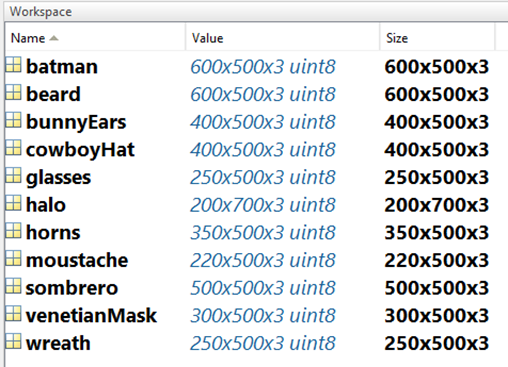

Type in the following command to look at an example of what we will be doing in this section:

       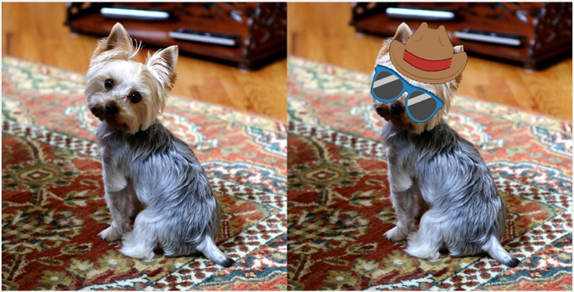

So the students can see they will be doing something very similar to the physical activity they just completed.

Tell the students that they will need to think of a plan that would turn the original image into the final image (applying the mask to the original image).  Record the students’ responses on a board or chart paper in the room. Similar to the physical activity, ask:

- *What is the first thing that you would need to do?  *

-     First, they will probably need to read in an input image, which has a face that they can put the mask on.

- *What would be the next step? *

-     Probably get the mask that they would like to put on the face.

- *Great, they have the face and the mask they want to apply. What next? *

-     They need to figure out where to apply the mask – on the head, on the eyes – so basically the location where the mask will need to be applied.

Only after they have all this – face, mask, and location – are they ready to actually apply the mask. 

Once the mask is applied they would probably like to view the final image as well. The final list of the steps should look like:

- Read in input image

- View input image (optional)

- Read in mask / Load mask

- View mask (optional)

- Get location of mask placement

- Apply mask on image at specified location

- View final image

Tell the students that these steps seem like a good starting point. Let’s try these out and see if we can apply a mask successfully to a face in an image. 

Ask the students to open the following script:

 
open 'ApplyMask.mlx'

Ask the students to run the script section-by-section by using the 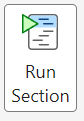 button in the **Editor **tab.  

The first section should clean up the Command Window, clear all the variables in the workspace, and close all open figure windows:

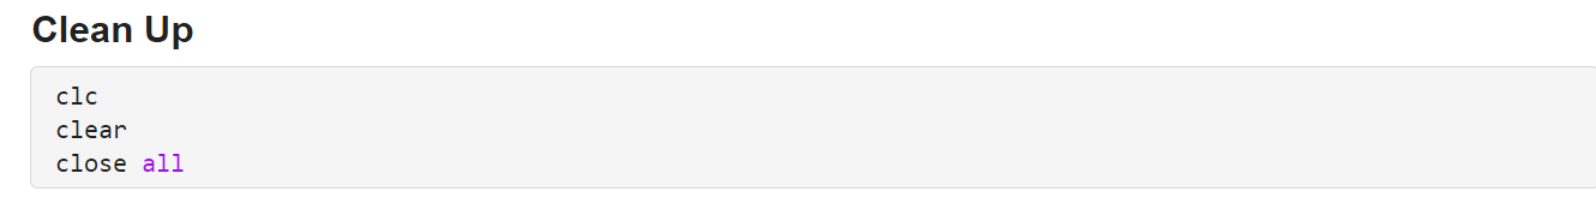

The next section reads in the input image

Next section displays the input image

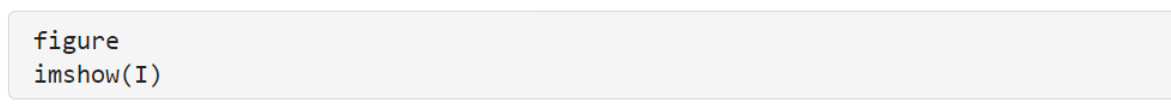

 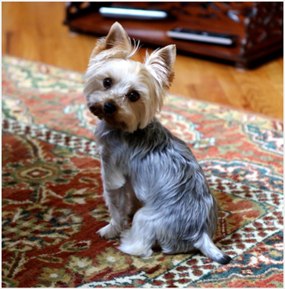

Next we load a MAT file. Tell the students that a MAT file is a special MATLAB file that stores variables and when we say load a MAT file, MATLAB loads all the stored variables to the Workspace.

Ask the students to watch the Workspace when you click on **Run and Advance.** This will load all the mask variables to the Workspace.

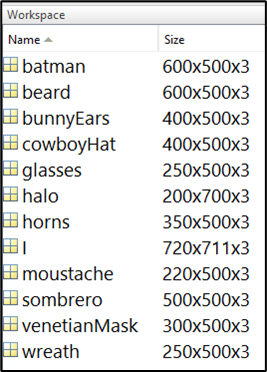

Next we display one of the masks – glasses.

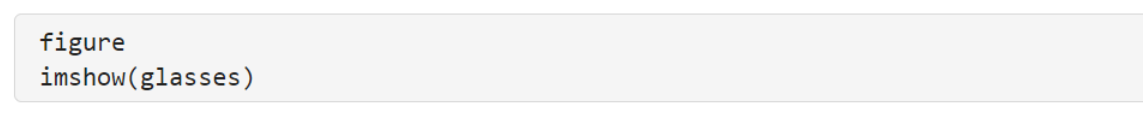

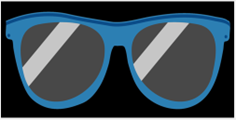

We then specify the location of where to place the mask. 

This means that begin placing the mask at 140th row and 180th column. This is similar to specifying the location of text in an image when creating memes.

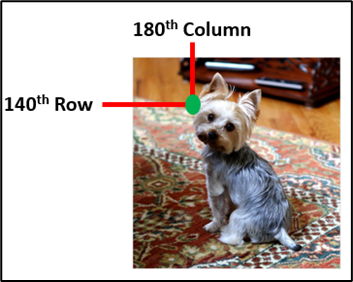

At this point students may ask how can they know just by looking at an image which row and column to specify as the location. Assure them that we will learn how to do that in just a few minutes but for the time being to trust you and move to the next section by clicking on **Run and Advance**. 

This section uses a new function `superImpose` the students haven’t seen yet. 

This function takes three inputs – the face image, the mask, and the location where the mask should be applied. So the purpose of this function is to apply the mask on the face image at the location specified.

The last step is to display the final superimposed image

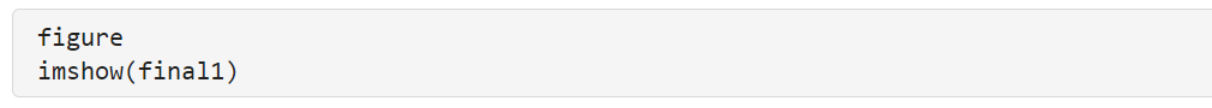

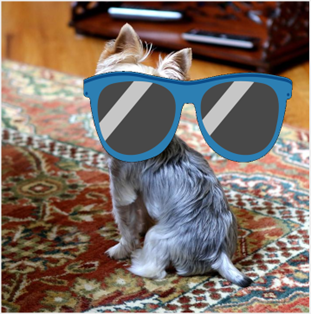

Ask:

- *Was what they were expecting?  *

-     No.

- *What do they think went wrong? *

-     Students should notice that the size of the glasses image is very big compared to the dog’s face image.

- *How can they fix the issue? *

-     Students should suggest that they resize the glasses image to be much smaller.  Encourage the students to think of ways to predict whether the mask is the appropriate size by guiding them to the size of the mask in the Workspace.

Tell the students that it looks like we need to add to another section to our algorithm – adjust the mask after loading and viewing it.  

Remind the students that they know a function that will allow them to adjust mask to be comparable to face in the image.

Use the function `imresize` to make the glasses smaller to half its original size as shown below.

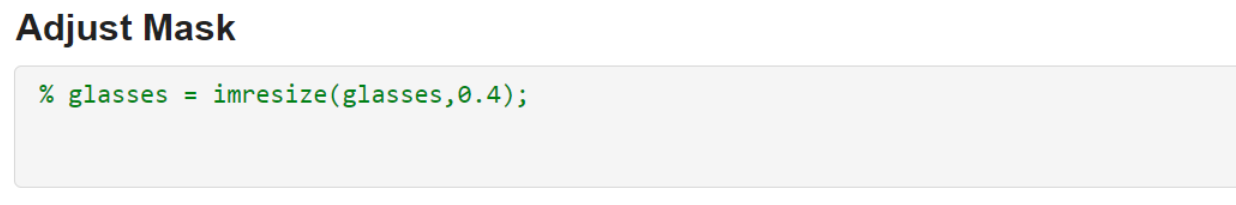 

Run the script again.

 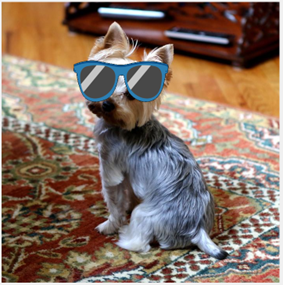

This is much better but it could still be made a little smaller. Also it might be helpful to rotate the glasses to fit the dog’s face better.

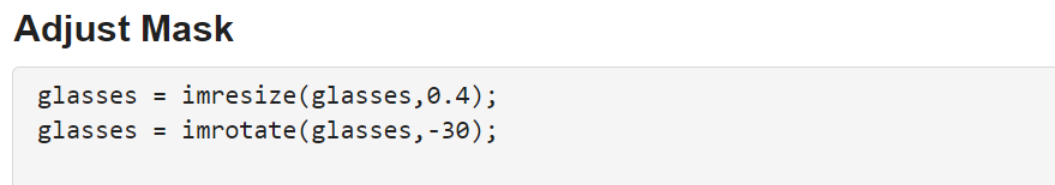

Positive angle input for `imrotate`, rotates the image anti-clockwise. Negative angle input rotates it clockwise.

 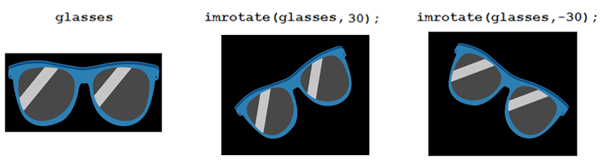

Ask the students to run the script again.

 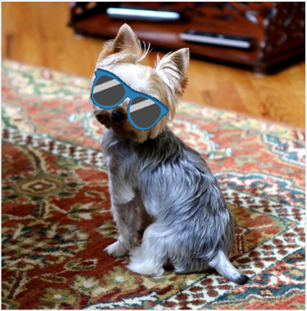

This is the result we expected!

Now let’s try and add a second mask to this image. The cowboy hat mask. 

We already have the face image and the `cowboyHat` variable in the Workspace. The only thing we need to apply it is to determine the location of where we would like to place the mask. 

Tell them there is a function, `getPoints,` which gives us the row and column location of a point we click in an image.

This opens up the image `I `and the mouse pointer turns into a long cross when hovered over the image.  

Ask:

- **What happens if you click on the image?  **

-     Students should notice that if  they click anywhere in the image, `getPoints` returns the row and column value of that point.

 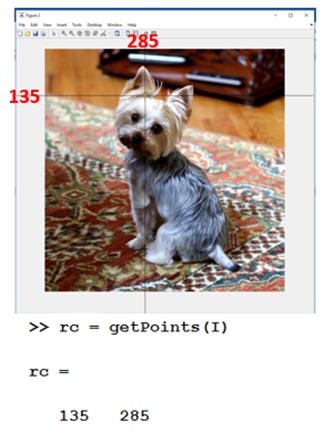

Instruct the students to try this out a few times, till it is clear to them what the function `getPoints` is doing.

 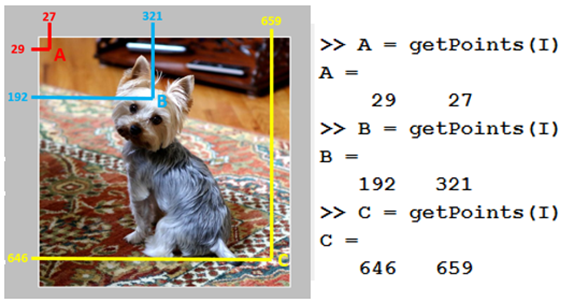

Instruct the students to use the function to find the row and column number of a rough location above the head (as that’s where we want to apply the cowboy hat mask). Tell them not to worry too much about getting the location perfect because it can be easily adjusted.

 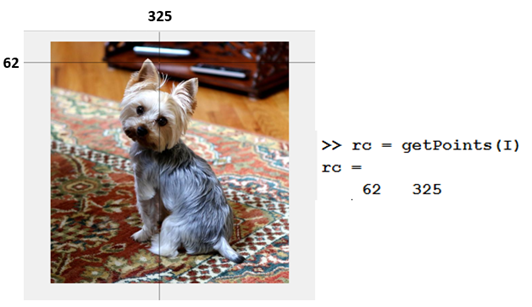

Go back to the script and put in those values as the location of the mask

 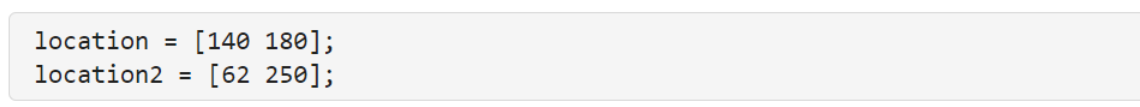

Now that we have all three inputs, we are ready to apply the mask.  have the face image, the mask and the location where we want to apply the mask – we are ready to apply the mask. When applying the mask, we need to remember to apply the mask to the final image, which has the glasses mask on, and not the original image. We would also like to display the new final image.

 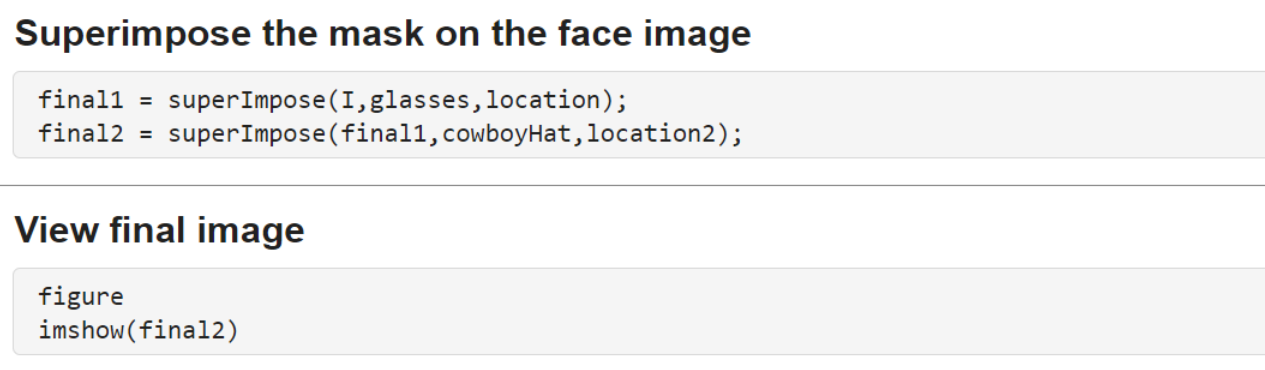

Run the script.

 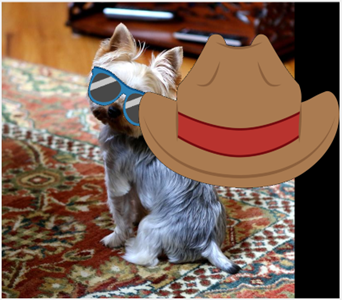

Again, we see that the mask is too big and needs to be adjusted.

 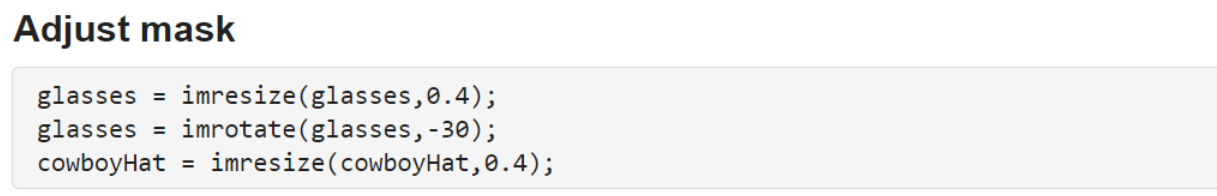

Run the script again.

 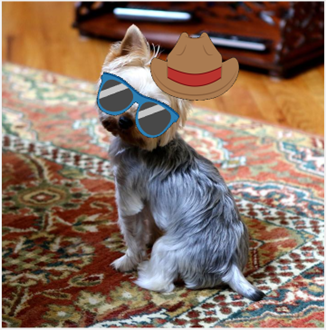

This is much better but the position of the mask seems to be a bit off. Ask:

- *How might you correct the position of the glasses?* 

-     Guide the students to think about what function gives us the location of where the glasses should be placed on the image.  The students should notice that the vector `location2` has the row and column number of where the mask should be applied.  

The `location2` vector contains the row and column number where the mask should be applied. If we adjust the row and column values, the mask can be moved around:

- To move left – reduce column numbers

- To move right – increase column numbers

- To move up – reduce row numbers

- To move down – increase row numbers

 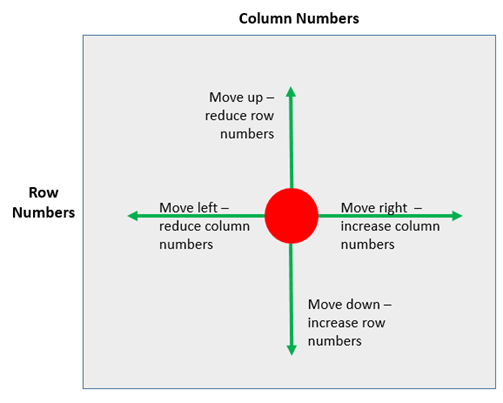

It may be a good idea to draw this figure on the board while explaining.

In this case, we need to move the mask to the left, so we need to reduce the column numbers. Ask them to reduce the column values in small increments of 10 pixels till they get the position correct.

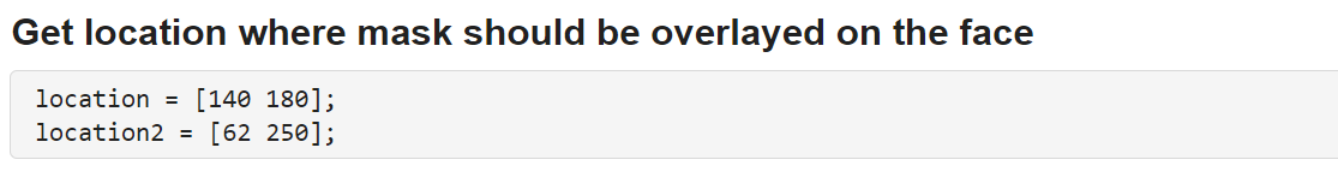

So, for this example the column value had to be reduced from 325 to 250 to get the location of mask correct. This will vary from image to image and students should get enough practice to get comfortable doing this.

 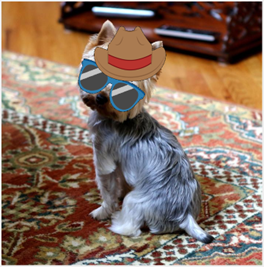

Tell the students that they are now ready to try adding masks to other images!

© COPYRIGHT 2024 by The MathWorks®, Inc.